clear; clc; close all;

% 1. CHARGEMENT DES DONNÉES
fprintf('Chargement des trajectoires...\n');

Chargement des trajectoires...


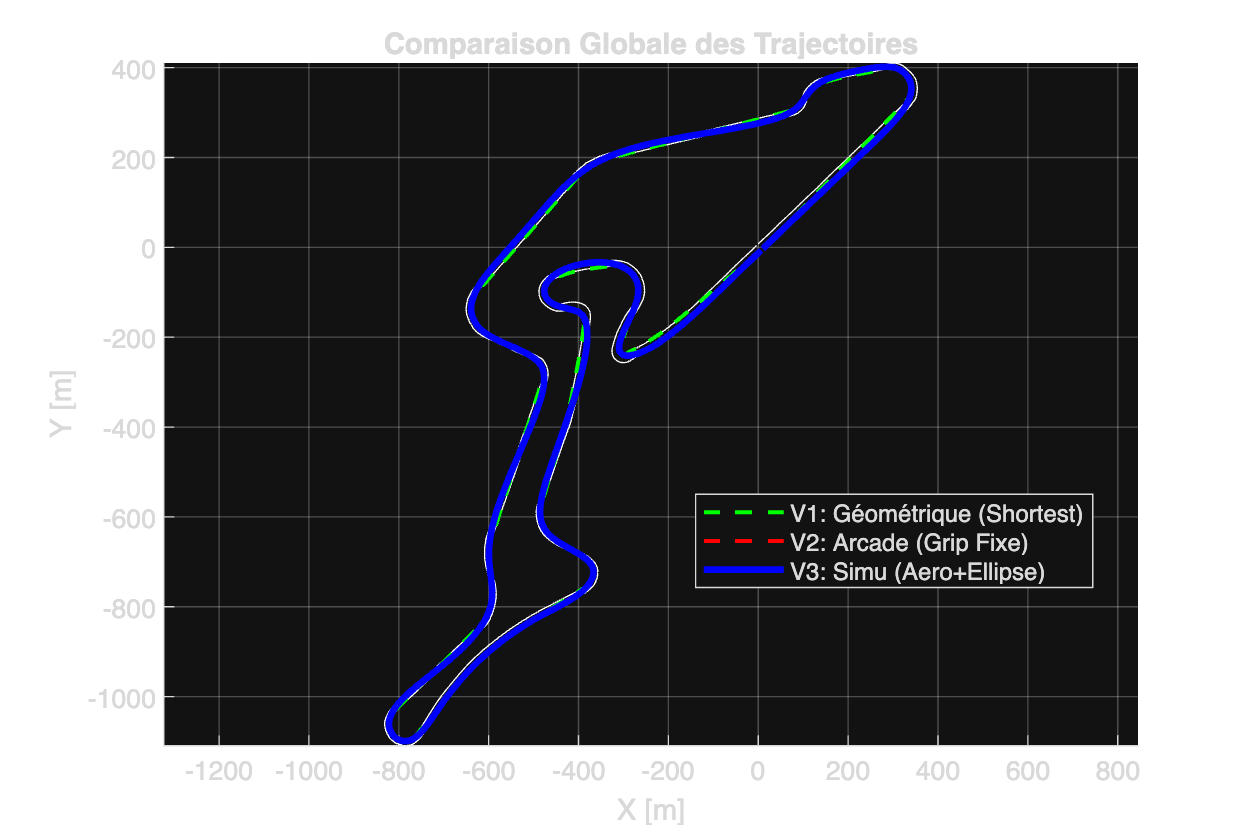

try
    v1 = load('DATA_V1_GEO.mat');
    v2 = load('DATA_V2_PURE.mat');
    v3 = load('DATA_V3_PURE.mat');
    
    % Chargement du circuit (limites)
    track = readmatrix('Circuits_Data/Nuerburgring_track.csv'); % Vérifie ton chemin
    x_in = track(:,1) - track(:,4) .* sin(atan2(diff([track(:,2);track(1,2)]), diff([track(:,1);track(1,1)])));
    y_in = track(:,2) + track(:,4) .* cos(atan2(diff([track(:,2);track(1,2)]), diff([track(:,1);track(1,1)])));
    x_out = track(:,1) + track(:,3) .* sin(atan2(diff([track(:,2);track(1,2)]), diff([track(:,1);track(1,1)])));
    y_out = track(:,2) - track(:,3) .* cos(atan2(diff([track(:,2);track(1,2)]), diff([track(:,1);track(1,1)])));
catch
    error('Fichiers manquants. Lance V1, V2, V3 avec les sauvegardes X/Y.');
end

% Chargement TUM (Optionnel)
raceline_file = 'Circuits_Data/Nuerburgring_raceline.csv';
tum_loaded = false;
if isfile(raceline_file)
    opts = detectImportOptions(raceline_file); opts.VariableNamingRule = 'preserve';
    data_race = readtable(raceline_file, opts);
    x_tum = data_race.("# x_m"); y_tum = data_race.y_m;
    tum_loaded = true;
end

% 2. FIGURE GLOBALE
figure('Name','Trajectory Comparison: V1 vs V2 vs V3', 'Color', 'w', 'Position', [50 50 1200 800]);
ax1 = subplot(1,1,1);
hold on; axis equal; grid on;

% Dessin Piste
plot(x_in, y_in, 'w-', 'LineWidth', 0.5);
plot(x_out, y_out, 'w-', 'LineWidth', 0.5);

% Dessin Trajectoires
p1 = plot(v1.x, v1.y, 'g--', 'LineWidth', 1.5, 'DisplayName', 'V1: Géométrique (Shortest)');
p2 = plot(v2.x, v2.y, 'r--', 'LineWidth', 1.5, 'DisplayName', 'V2: Arcade (Grip Fixe)');
p3 = plot(v3.x, v3.y, 'b-', 'LineWidth', 2.5, 'DisplayName', 'V3: Simu (Aero+Ellipse)');
if tum_loaded
    plot(x_tum, y_tum, 'Color', [0.5 0.5 0.5], 'LineWidth', 1, 'DisplayName', 'Ref: TUM');
end

title('Comparaison Globale des Trajectoires');
legend([p1 p2 p3], 'Location', 'best');
xlabel('X [m]'); ylabel('Y [m]');

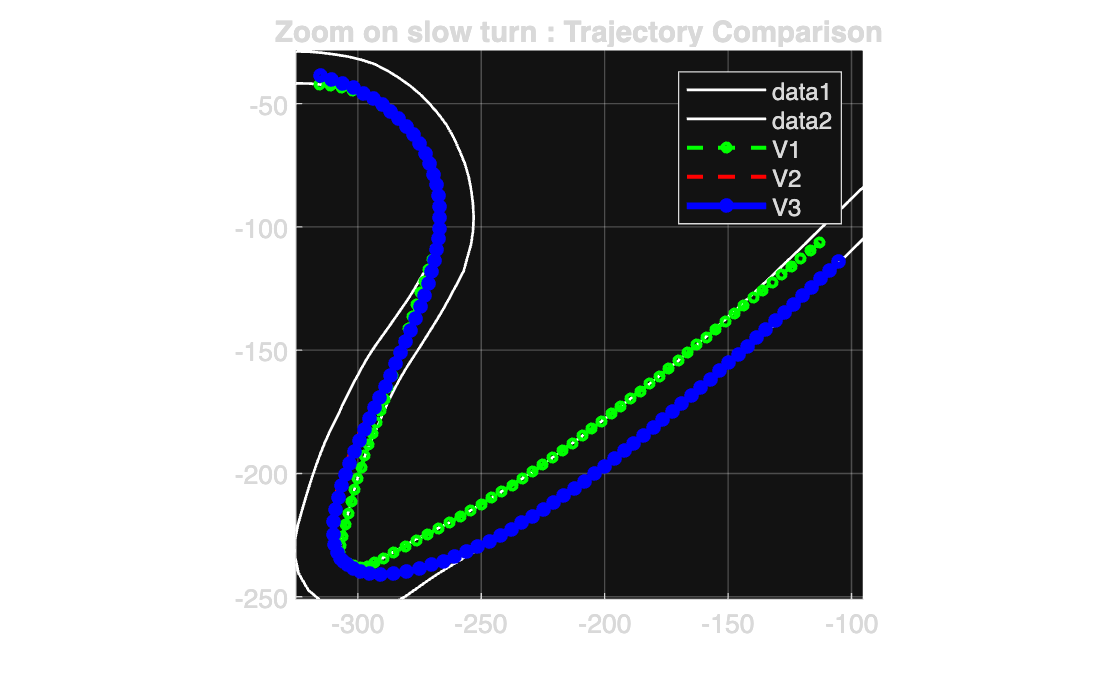


% 3. ANALYSE DE ZOOM (ZOOM SUR UNE ÉPINGLE)
% On cherche un point où la vitesse V3 est très lente (signe d'une épingle)
[min_val, idx_slow] = min(v3.v); 
range = (idx_slow - 50) : (idx_slow + 50); % 50 points avant/après
range = range(range > 0 & range < length(v3.x));

figure('Name','Zoom: Hairpin Analysis', 'Color', 'w');
hold on; axis equal; grid on;
% Limites piste locales
plot(x_in, y_in, 'w-', 'LineWidth',1);
plot(x_out, y_out, 'w-', 'LineWidth', 1);

% Trajectoires locales
plot(v1.x(range), v1.y(range), 'g--o', 'MarkerSize', 3, 'LineWidth', 1.5, 'DisplayName', 'V1');
plot(v2.x(range), v2.y(range), 'r--', 'LineWidth', 1.5, 'DisplayName', 'V2');
plot(v3.x(range), v3.y(range), 'b-o', 'MarkerSize', 3, 'LineWidth', 2.5, 'DisplayName', 'V3');

if tum_loaded
    % Trouver le point TUM le plus proche pour centrer
    [~, idx_tum] = min((x_tum - v3.x(idx_slow)).^2 + (y_tum - v3.y(idx_slow)).^2);
    range_tum = (idx_tum-50):(idx_tum+50);
    plot(x_tum(range_tum), y_tum(range_tum), 'Color', [0.6 0.6 0.6], 'DisplayName', 'TUM');
end

% Centrer la vue
xlim([min(v3.x(range))-10, max(v3.x(range))+10]);
ylim([min(v3.y(range))-10, max(v3.y(range))+10]);
legend;
title('Zoom on slow turn : Trajectory Comparison');